# Intake: Throttle Open Area

## Throttle Open Area

For the details of equations appearing in this Live Script, see for example "7.3 Throttle Flow Modeling" in "Modeling and Control of Engines and Drivelines" (L. Eriksson, L. Nielsen, ISBN: 978-1-118-47999-5, Wiley 2014).

syms D_thr S_leak theta_rest theta_thr

% parameters
S_leak_cm2 = paramfcn_intake_S_leak_cm2()

S_leak_cm2 = 1

D_thr_cm = paramfcn_intake_D_thr_cm()

D_thr_cm = 18

theta_rest_deg = paramfcn_intake_thr_rest_deg()

theta_rest_deg = 3

% Simple algebraic formula. This tends to have a large error at large throttle
% openings, but parameters are straightfoward to understand.
S_thr = pi*(D_thr/2)^2 * (1 - cos( theta_thr )/cos( theta_rest )) + S_leak

$$S\_thr = S_{\mathrm{leak}}-\frac{\pi \,{D_{\mathrm{thr}}}^{2}\,\left(\frac{\cos\left(\theta_{\mathrm{thr}}\right)}{\cos\left(\theta_{\mathrm{rest}}\right)}-1\right)}{4}$$

dS_thr = diff(S_thr, theta_thr)

$$dS\_thr = \frac{\pi \,{D_{\mathrm{thr}}}^{2}\,\sin\left(\theta_{\mathrm{thr}}\right)}{4\,\cos\left(\theta_{\mathrm{rest}}\right)}$$

Apply valuation functions for comprehension & visualization

This is to check that the equations and parameter values are reasonable.

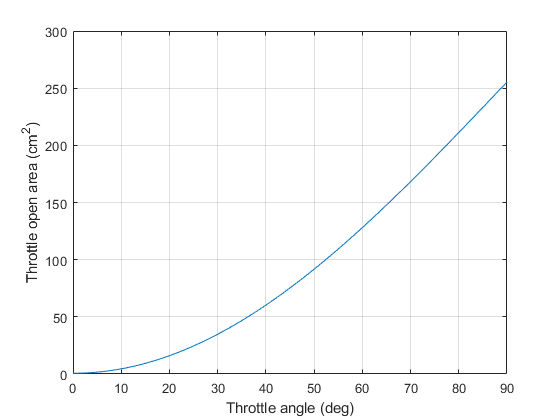

F = subs(S_thr, S_leak,     S_leak_cm2);
F = subs(F,     D_thr,      D_thr_cm);
F = subs(F,     theta_rest, theta_rest_deg/180*pi);
deg = linspace(0, 90, 100);
y1 = double(subs(F, theta_thr, deg/180*pi));
figure
plot(deg, y1)
hold on
grid on
xlabel('Throttle angle (deg)')
ylabel('Throttle open area (cm^2)')

As can be seen from the above plot, the curve does not level off near the large throttle angle, resulting in large error in the open area estimation. Ideally, we want to use physically meaningful parameters and also use more accurate area curve.

The polynomial formula in the next section is introduced to improve the open area estimation.

We will also generate a Matlab function to automate the calculation of polynomical coefficients from physically meaningful parameters.

## Polynomial Formula

Find the four coefficients of a thrid order polynomial with the following conditions to meet:

- Same opening area at the rest angle as the above simple algebraic formula (expr1==0 below)

- Same opening area at 90 degrees as the above simple algebraic formula (expr2==0 below)

- Same slope at the rest angle as the above simple algebraic formula (expr3==0 below)

- Zero slope at 90 degrees (expr4==0 below)

syms  k_0  k_1  k_2  k_3  z
S_poly = k_0 + k_1*z + k_2*z^2 + k_3*z^3

$$S\_poly = k_{3}\,z^{3}+k_{2}\,z^{2}+k_{1}\,z+k_{0}$$

dS_poly = diff(S_poly, z)

$$dS\_poly = 3\,k_{3}\,z^{2}+2\,k_{2}\,z+k_{1}$$

% 1. Same opening area at the rest angle as the above simple algebraic formula:
expr1 = subs(S_poly, z, theta_rest_deg/180*pi) - ...
        subs(S_thr, theta_thr, theta_rest_deg/180*pi)

$$expr1 = \frac{\pi \,\left(\frac{\cos\left(\frac{\pi }{60}\right)}{\cos\left(\theta_{\mathrm{rest}}\right)}-1\right)\,{D_{\mathrm{thr}}}^{2}}{4}-S_{\mathrm{leak}}+k_{0}+\frac{\pi \,k_{1}}{60}+\frac{k_{2}\,\pi^{2}}{3600}+\frac{k_{3}\,\pi^{3}}{216000}$$

% 2. Same opening area at 90 degrees as the above simple algebraic formula:
expr2 = subs(S_poly, z, pi/2) - subs(S_thr, theta_thr, pi/2)

$$expr2 = -\frac{\pi \,{D_{\mathrm{thr}}}^{2}}{4}-S_{\mathrm{leak}}+k_{0}+\frac{\pi \,k_{1}}{2}+\frac{k_{2}\,\pi^{2}}{4}+\frac{k_{3}\,\pi^{3}}{8}$$

% 3. Same slope at the rest angle as the above simple algebraic formula
expr3 = subs(dS_poly, z, theta_rest_deg/180*pi) ...
        - subs(dS_thr, theta_thr, theta_rest_deg/180*pi)

$$expr3 = k_{1}+\frac{\pi \,k_{2}}{30}+\frac{k_{3}\,\pi^{2}}{1200}-\frac{\pi \,{D_{\mathrm{thr}}}^{2}\,\sin\left(\frac{\pi }{60}\right)}{4\,\cos\left(\theta_{\mathrm{rest}}\right)}$$

% 4. Zero slope at 90 degrees
expr4 = subs(dS_poly, z, pi/2)

$$expr4 = k_{1}+\pi \,k_{2}+\frac{3\,k_{3}\,\pi^{2}}{4}$$

The above four equations are linear with respect to $k_0$, $k_1$, $k_2$, $k_3$. Thus, they can be solved analytically. In what follows, they are solved numerically at first because numerical approach works more generally than analytic approach. Analytic approach will be performed later.

## Solve numerically

e1 = subs(expr1, [S_leak,     D_thr,    theta_rest], ...
                 [S_leak_cm2, D_thr_cm, theta_rest_deg/180*pi]);
e2 = subs(expr2, [S_leak,     D_thr], ...
                 [S_leak_cm2, D_thr_cm]);
e3 = subs(expr3, [D_thr,    theta_rest], ...
                 [D_thr_cm, theta_rest_deg/180*pi]);
e4 = expr4;
fcn = matlabFunction( [e1; e2; e3; e4], 'Vars',{[k_0, k_1, k_2, k_3]});
sol = fsolve(fcn, [0,0,0,0])


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



sol =     1.1813  -20.6454  335.4633 -139.5860


## Compare the result

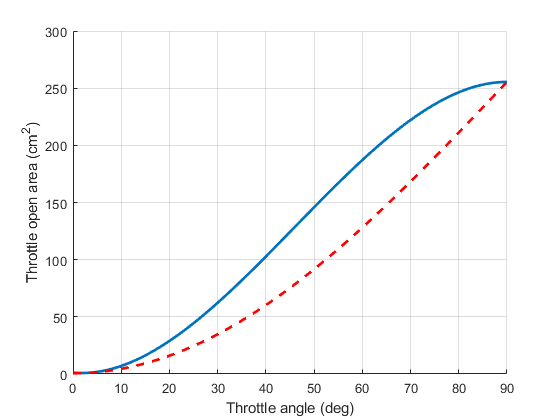

x = deg/180*pi;  % degress to radians
y2 = sol(1) + sol(2)*x + sol(3)*x.^2 + sol(4)*x.^3;
figure
hold on
p1 = plot(deg, y2, '-');
p1.LineWidth = 2;
p1.Color = [0 0.447 0.741];  % default dark blue
p2 = plot(deg, y1, '--');
p2.LineWidth = 2;
p2.Color = 'red';
grid on
xlabel('Throttle angle (deg)')
ylabel('Throttle open area (cm^2)')

The red dashed curve is the original formula presented earlier. The blue solid curve is the polynomial version.

## Generate a separate Matlab function file for use with Simscape

matlabFunction( [expr1; expr2; expr3; expr4], ...
        'File','throttleParamEqs', ...
        'Vars',{[k_0, k_1, k_2, k_3], S_leak, D_thr, theta_rest})

ans = function_handle with value:
    @throttleParamEqs


The generated Matlab function file is used in antoher Matlab function file **throttleOpenAreaCoeff.m**, which looks as follows and is used to set the parameter values of the Engine Intake component implemented in Simscape.

Run this function on Command Window as follows and confirm that you get the expected results.

## Solve Analytically

sol = solve([expr1==0, expr2==0, expr3==0, expr4==0], [k_0,k_1,k_2,k_3]);
sol.k_0

$$ans = \frac{97556\,S_{\mathrm{leak}}\,\cos\left(\theta_{\mathrm{rest}}\right)+24389\,\pi \,{D_{\mathrm{thr}}}^{2}\,\cos\left(\theta_{\mathrm{rest}}\right)-24300\,\pi \,{D_{\mathrm{thr}}}^{2}\,\cos\left(\frac{\pi }{60}\right)-435\,{D_{\mathrm{thr}}}^{2}\,\pi^{2}\,\sin\left(\frac{\pi }{60}\right)}{97556\,\cos\left(\theta_{\mathrm{rest}}\right)}$$

sol.k_1

$$ans = -\frac{60\,\left(45\,{D_{\mathrm{thr}}}^{2}\,\cos\left(\frac{\pi }{60}\right)-116\,\pi \,{D_{\mathrm{thr}}}^{2}\,\sin\left(\frac{\pi }{60}\right)\right)}{24389\,\cos\left(\theta_{\mathrm{rest}}\right)}$$

sol.k_2

$$ans = \frac{15\,\left(5580\,{D_{\mathrm{thr}}}^{2}\,\cos\left(\frac{\pi }{60}\right)-1769\,\pi \,{D_{\mathrm{thr}}}^{2}\,\sin\left(\frac{\pi }{60}\right)\right)}{24389\,\pi \,\cos\left(\theta_{\mathrm{rest}}\right)}$$

sol.k_3

$$ans = -\frac{900\,\left(120\,{D_{\mathrm{thr}}}^{2}\,\cos\left(\frac{\pi }{60}\right)-29\,\pi \,{D_{\mathrm{thr}}}^{2}\,\sin\left(\frac{\pi }{60}\right)\right)}{24389\,\pi^{2}\,\cos\left(\theta_{\mathrm{rest}}\right)}$$

% WISH: want to extract symbols from the above solutions.
%   Expected returned symbols are S_leak, D_thr and theta_rest.
fcn = matlabFunction( [sol.k_0, sol.k_1, sol.k_2, sol.k_3], ...
    'Vars',{S_leak, D_thr, theta_rest})

fcn = function_handle with value:
    @(S_leak,D_thr,theta_rest)[(S_leak.*cos(theta_rest)+D_thr.^2.*pi.*cos(theta_rest).*(1.0./4.0)-D_thr.^2.*pi.*cos(pi.*(1.0./6.0e1)).*2.490877034728771e-1-D_thr.^2.*pi.^2.*sin(pi.*(1.0./6.0e1)).*4.4589774078478e-3)./cos(theta_rest),(D_thr.^2.*cos(pi.*(1.0./6.0e1)).*(-1.107056459879454e-1)+D_thr.^2.*pi.*sin(pi.*(1.0./6.0e1)).*(2.4e2./8.41e2))./cos(theta_rest),(D_thr.^2.*cos(pi.*(1.0./6.0e1)).*3.431875025626307-D_thr.^2.*pi.*sin(pi.*(1.0./6.0e1)).*(9.15e2./8.41e2))./(pi.*cos(theta_rest)),(1.0./pi.^2.*(D_thr.^2.*cos(pi.*(1.0./6.0e1)).*1.2e2-D_thr.^2.*pi.*sin(pi.*(1.0./6.0e1)).*2.9e1).*(-3.69018819959818e-2))./cos(theta_rest)]


fcn(S_leak_cm2, D_thr_cm, theta_rest_deg/180*pi)

ans =     1.1813  -20.6454  335.4633 -139.5860


Check that the above values are the same as those returned from fsolve().

Generate a Matlab function file.

matlabFunction( [sol.k_0, sol.k_1, sol.k_2, sol.k_3], ...
    'File','throttleParamEqsAnalytic', ...
    'Vars',{S_leak, D_thr, theta_rest})

ans = function_handle with value:
    @throttleParamEqsAnalytic
